# Performance for Different Choices of mC and kC

clear all

output_PI_JI_MCxKC        % load performance data


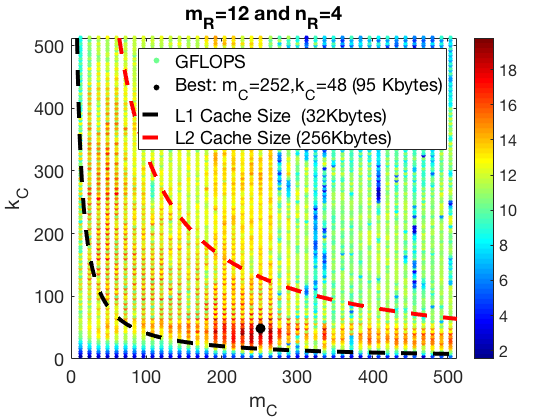

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

colorbar;   % show the color bar
colormap jet;

% create scatter plot of performance
scatter( data(:,2), data(:,3), 20, data(:,7), 'filled', ...
    'DisplayName', 'GFLOPS');

[ maxvalue, imax ] = max( data(:,7) );

scatter( data(imax,2), data(imax,3), 100, data(imax,7), 'black', ...
    'filled', 'DisplayName', sprintf( 'Best: m_C=%d,k_C=%d (%d Kbytes)', ...
    data(imax,2), data( imax,3), ...
    round(data(imax,2)*data(imax,3)*8/1024) ) );

Doubles_in_L1_Cache = 32*1024/8;

MC = [1:1:512];
KC = ones( size( MC ) ) * Doubles_in_L1_Cache ./ MC;
plot( MC, KC, 'LineStyle', '--', 'LineWidth', 4, ...
    'Color', 'black', ...
    'DisplayName', 'L1 Cache Size  (32Kbytes)' );

Doubles_in_L2_Cache = 256*1024/8;

KC = ones( size( MC ) ) * Doubles_in_L2_Cache ./ MC;

plot( MC, KC, 'LineStyle', '--', 'LineWidth', 4, ...
    'Color', 'red', ...
    'DisplayName', 'L2 Cache Size (256Kbytes)' );

% Create title
title( 'm_R=12 and n_R=4')
% Create ylabel
ylabel( 'k_C', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'm_C', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeast','FontSize',18);

axis( [0 512 0 512 ] );